clc
clear all

axis([0 20 0 20])
grid minor
hold on
n=0

n = 0

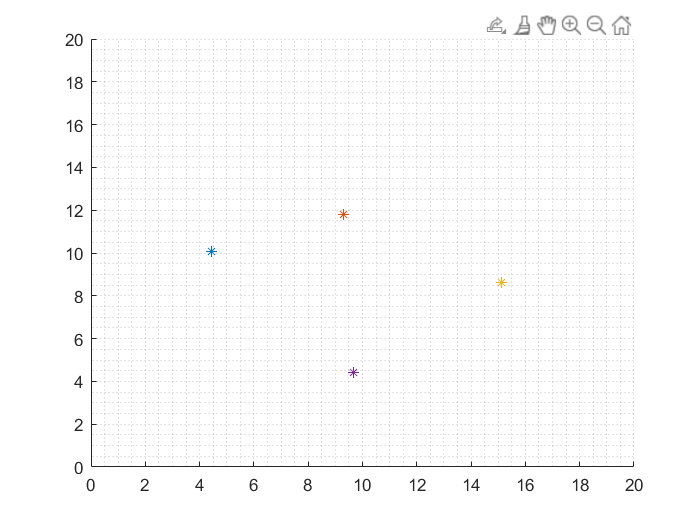

while n < 4
    [x,y]=ginput(1);
    plot(x,y,'*');
    n=n+1;
    point(:,n)=[x,y];
end


u1=.0;
u2=1/3;
u3=2/3;
u4=1;


U1=u1.^[3 2 1 0]

U1 =      0     0     0     1


U2=u2.^[3 2 1 0]

U2 =     0.0370    0.1111    0.3333    1.0000


U3=u3.^[3 2 1 0]

U3 =     0.2963    0.4444    0.6667    1.0000


U4=u4.^[3 2 1 0]

U4 =      1     1     1     1


UU = [U1;U2;U3;U4]

UU =          0         0         0    1.0000
    0.0370    0.1111    0.3333    1.0000
    0.2963    0.4444    0.6667    1.0000
    1.0000    1.0000    1.0000    1.0000


u=u1:0.01:u4

u =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


u=u'

u =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


U=u.^[3 2 1 0]

U =          0         0         0    1.0000
    0.0000    0.0001    0.0100    1.0000
    0.0000    0.0004    0.0200    1.0000
    0.0000    0.0009    0.0300    1.0000
    0.0001    0.0016    0.0400    1.0000
    0.0001    0.0025    0.0500    1.0000
    0.0002    0.0036    0.0600    1.0000
    0.0003    0.0049    0.0700    1.0000
    0.0005    0.0064    0.0800    1.0000
    0.0007    0.0081    0.0900    1.0000


Pc=U*inv(UU)*point'

Pc =     4.4383   10.0701
    4.4534   10.2304
    4.4800   10.3829
    4.5178   10.5277
    4.5666   10.6650
    4.6258   10.7947
    4.6953   10.9171
    4.7746   11.0321
    4.8636   11.1400
    4.9617   11.2409


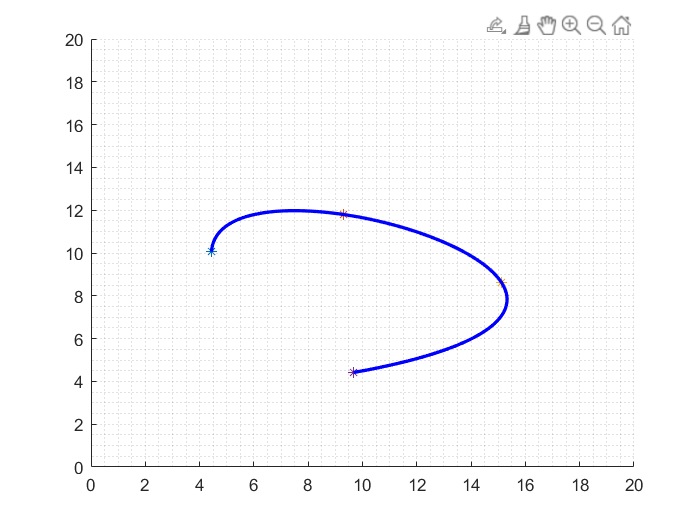

plot(Pc(:,1),Pc(:,2),'b',"LineWidth",2)